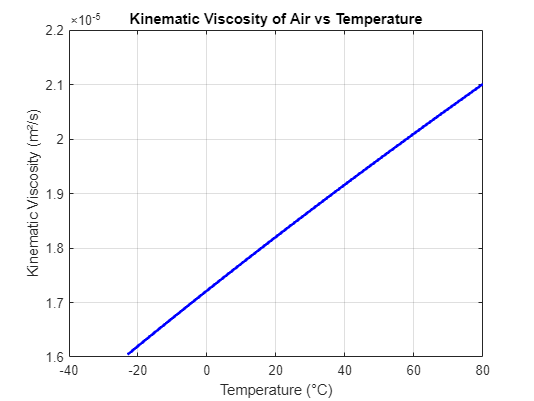


% Define the temperature range in Kelvin
T = 273.15 + (-23:80);  % Temperature from 0°C to 100°C

% Calculate kinematic viscosity for air at each temperature
KinVisc_T = arrayfun(@(temp) py.CoolProp.CoolProp.PropsSI('V', 'T', temp, 'P', 101325, 'Air'), T);

% Plotting kinematic viscosity vs temperature
figure;
plot(T - 273.15, KinVisc_T, 'b-', 'LineWidth', 2);  % Temperature in °C
xlabel('Temperature (°C)');
ylabel('Kinematic Viscosity (m²/s)');
title('Kinematic Viscosity of Air vs Temperature');
grid on;